# Error de distretització

## O(h) error lineal

f=@log

f = function_handle with value:
    @log

n=0:4;
h=10.^(-n); %1, 0.1, 0.01 ... cada vegada mes petit
F1=(f(2+h)-f(2))./h

F1 =       0.40547       0.4879      0.49875      0.49988      0.49999


[ea, er, d1,t1] = funerror(F1, 0.5);

er_abs =      0.094535     0.012098    0.0012458   0.00012496     1.25e-05


er_rel =       0.23315     0.024797    0.0024979   0.00024998      2.5e-05


d =      0     1     2     3     4


t =      0     1     2     3     4


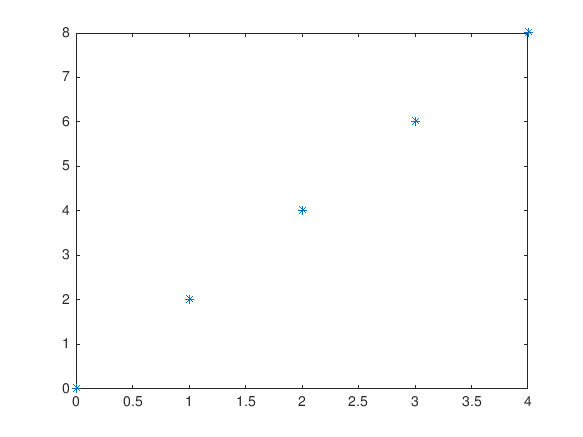

plot(n, t, '*')

## O(h^2) error quadratic

n=0:4;
h=10.^(-n);
F2=(f(2+h)-f(2-h))./(2*h)

F2 =       0.54931      0.50042          0.5          0.5          0.5


[ea, er, d2,t2] = funerror(F2, 0.5);

er_abs =      0.049306   0.00041729   4.1667e-06   4.1667e-08   4.1683e-10


er_rel =      0.089761   0.00083389   8.3334e-06   8.3333e-08   8.3367e-10


d =      1     3     5     7     9


t =      0     2     4     6     8


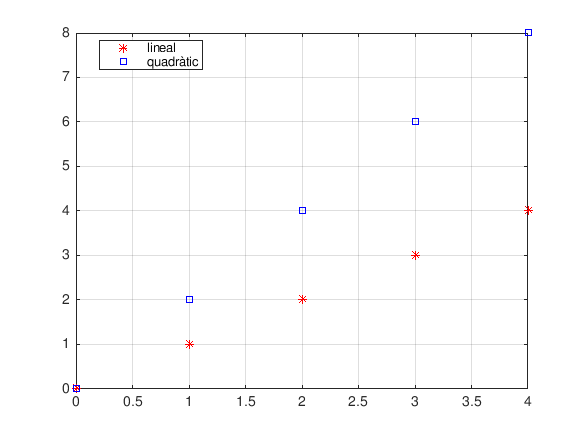

plot(n, t1, 'r*', n, t2, 'bs'), legend('lineal', 'quadràtic', 'Location', 'best'), grid on